# **同轴线内部的磁场分布**

**        同轴线是指用来传递信息的一对导体按照一层圆筒式的外导体套在内导体（一根细芯）外面，两个导体间用绝缘材料互相隔离的结构制造的， 外层导体和中心轴芯线的圆心在同一个轴心上。**

- **定义参数**

I=1;   %自定义电流值
r=0:0.01:1;%r归一化
r1=0.2;  %自定义内导体外径
r2=0.5;  %自定义外导体内径
r3=0.8;  %自定义外导体外径

  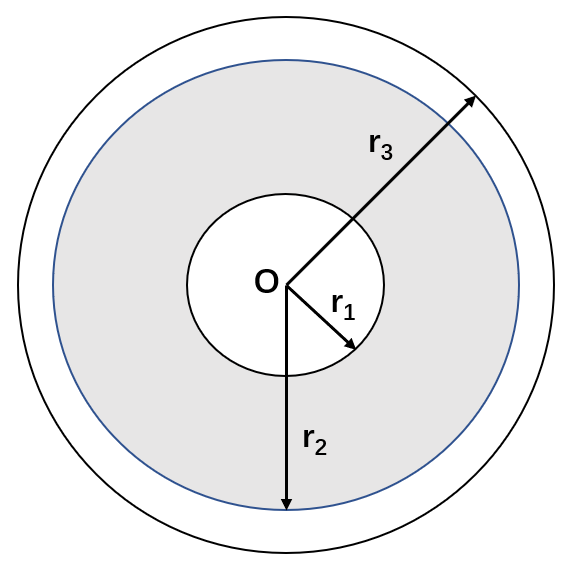

**        同轴线截面如图所示，其导波装置是双导体结构，传输电磁波的主模式是TEM波。从场的观点看，同轴线的边界条件既能支持TEM波传输，也能支持TE波或TM波传输，究竟哪些波能在同轴线中传输，则取决于同轴线的尺寸和电磁波的频率。忽略同轴线端部的边缘效应，由安培环路定律可以求得同轴线各部分区域内的磁场强度在圆柱坐标系中分别为:**


$$\begin{array}{l}
\left\lbrace \begin{array}{ll}
H_i =\frac{\textrm{Ir}}{2\pi {r_1 }_{\;\;}^2 }, & r\le r_1 \left(\textrm{内导体内}\right)\\
H_d =\frac{I}{2\pi r}, & r_1 \le r\le r_2 \left(\textrm{电介质内}\right)
\end{array}\right.\\
\left\lbrace \begin{array}{ll}
H_e =\frac{I}{2\pi r}\frac{{r_3 }^2 -{r_{\;} }^2 }{{r_3 }^2 -{r_2 }^2 }, & r_2 \le r\le r_3 \left(\textrm{外导体内}\right)\\
{H_e }^{\prime } =0, & r\ge r_3 \left(\textrm{外导体外}\right)
\end{array}\right.
\end{array}$$


- 分段计算磁场强度

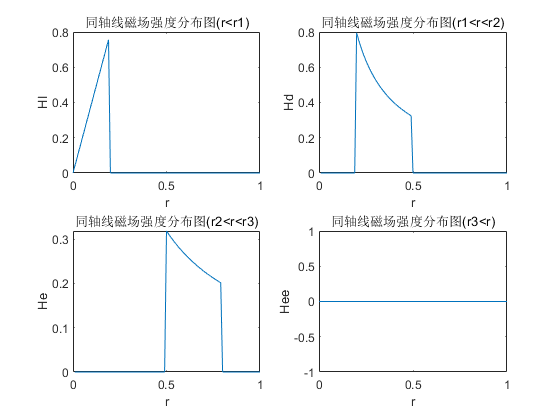

%内导体内部磁场强度HI
HI=I*r./(2*pi*r1^2).*(r<r1);
subplot(2,2,1);
plot(r,HI);
xlabel('r');ylabel('HI');
title('同轴线磁场强度分布图(r<r1)');
%内外导体之间磁场强度Hd
Hd=I./(2*pi*r).*(r>=r1&r<r2);
subplot(2,2,2);
plot(r,Hd);
xlabel('r');ylabel('Hd');
title('同轴线磁场强度分布图(r1<r<r2)');
%外导体内部场强He
He=I*(r3^2-r2^2)./(2*pi*r*(r3^2-r2^2)).*(r>=r2&r<r3);
subplot(2,2,3);
plot(r,He);
xlabel('r');ylabel('He');
title('同轴线磁场强度分布图(r2<r<r3)');
%外导体外部场强Hee
Hee=0.*(r>=r3);
subplot(2,2,4);
plot(r,Hee);
xlabel('r');ylabel('Hee');
title('同轴线磁场强度分布图(r3<r)');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- 同轴线磁场强度分布图

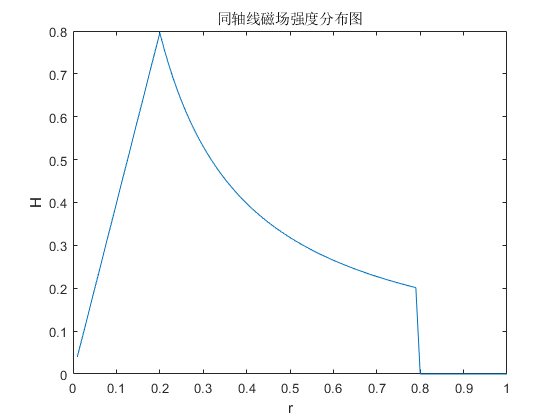

figure
H=I.*r./((2*pi)*r1^2).*(r<r1)+I./(2*pi.*r).*(r>=r1&r<r2)+I*(r3^2-r2^2)./(2*pi.*r*(r3^2-r2^2)).*(r>=r2&r<r3)+0.*(r>=r3);
plot(r,H);
xlabel('r');ylabel('H');
title('同轴线磁场强度分布图');
set(gcf,'Visible','on');   	    %强制图片弹出显示